# 열 합치기

A=[1,2,3,4];
B=[5,6];
C=[7,8,9];
ARRAY=zeros(5);
ARRAY(1,1:numel(A)) = A;
ARRAY(2,1:numel(B)) = B;
ARRAY(3,1:numel(C)) = C;
ARRAY

ARRAY =      1     2     3     4     0
     5     6     0     0     0
     7     8     9     0     0
     0     0     0     0     0
     0     0     0     0     0



%https://kr.mathworks.com/matlabcentral/fileexchange/22909-padcat
A=[1,2,3,4];
B=[5,6];
C=[7,8,9];
[ARRAY, tf] = padcat(A,B,C) % pad with NaNs

ARRAY =      1     2     3     4
     5     6   NaN   NaN
     7     8     9   NaN


tf = 3×4 logical array
   1   1   1   1
   1   1   0   0
   1   1   1   0


ARRAY(~tf) = 0 % replace those NaNs with zeros

ARRAY =      1     2     3     4
     5     6     0     0
     7     8     9     0



% https://kr.mathworks.com/matlabcentral/answers/16374-adding-elements-to-an-array
A = [1 2; 3 4]

A =      1     2
     3     4


B = [5 6; 7 8]

B =      5     6
     7     8


H1 = [A B]

H1 =      1     2     5     6
     3     4     7     8


H2 = horzcat(A,B)

H2 =      1     2     5     6
     3     4     7     8


H3 = cat(2,A,B)

H3 =      1     2     5     6
     3     4     7     8


V1 = [A; B]

V1 =      1     2
     3     4
     5     6
     7     8


V2 = vertcat(A,B)

V2 =      1     2
     3     4
     5     6
     7     8


V3 = cat(1,A,B)

V3 =      1     2
     3     4
     5     6
     7     8


# 서로 다른 데이타 - interpolation

% https://kr.mathworks.com/matlabcentral/answers/50958-how-to-plot-the-vectors-having-different-length
X_known = [1 2 3  6  8 10] ;
Y_known = [2 5 6 11 18 23] ;
X_desired = 1:10 

X_desired =      1     2     3     4     5     6     7     8     9    10


Y_desired = interp1(X_known, Y_known, X_desired)

Y_desired =     2.0000    5.0000    6.0000    7.6667    9.3333   11.0000   14.5000   18.0000   20.5000   23.0000


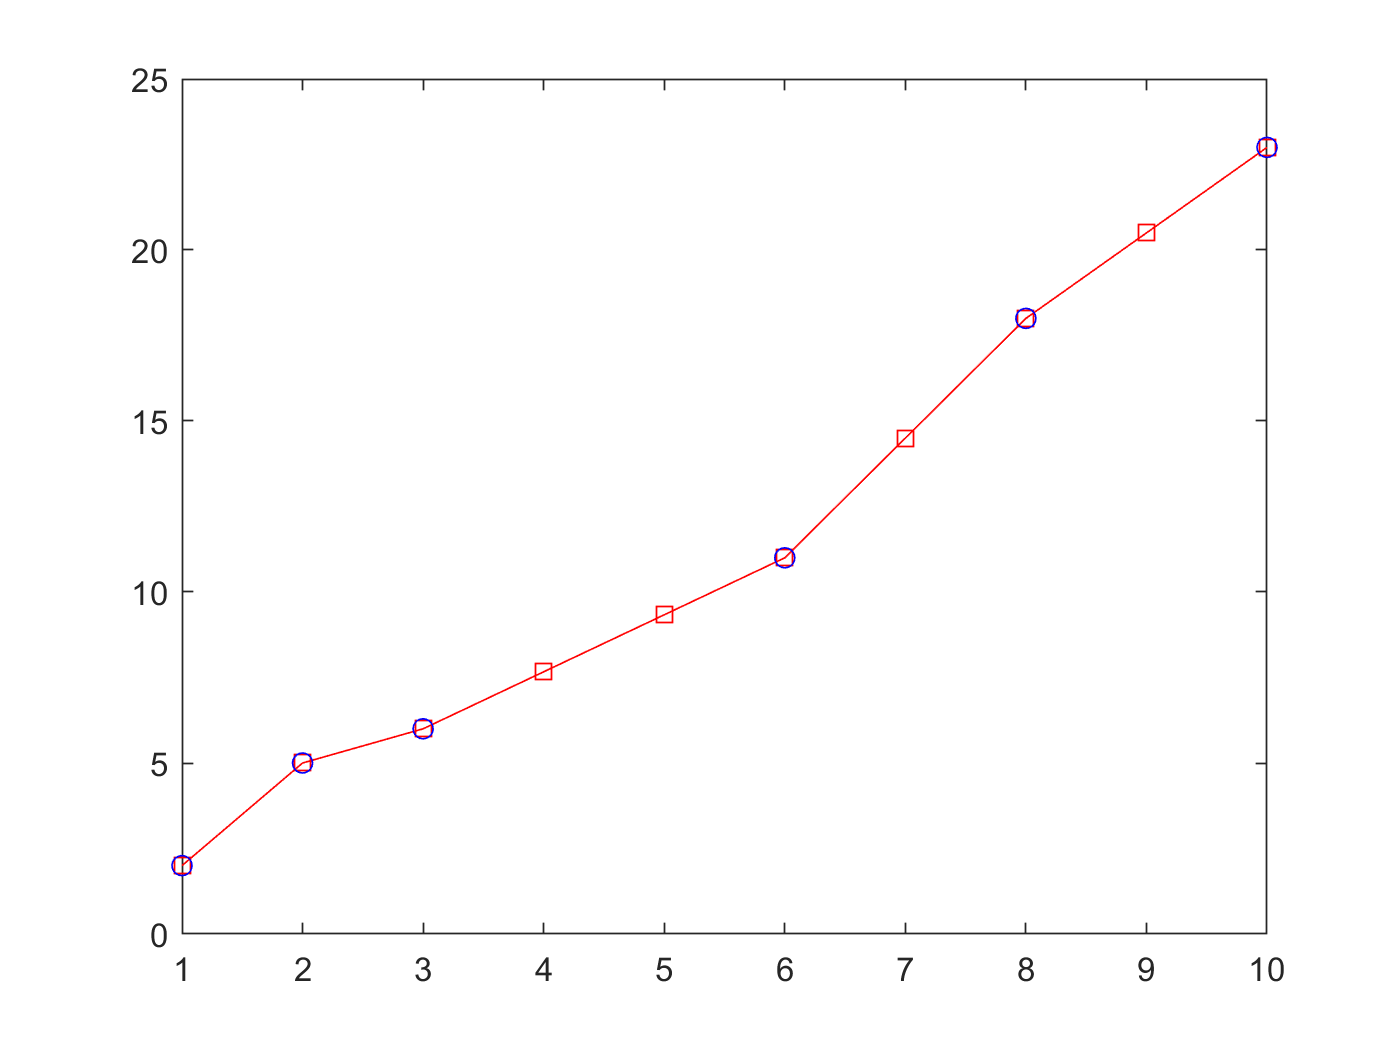

plot(X_desired, Y_desired,'rs-', X_known, Y_known,'bo')

# structure 합치기

% https://kr.mathworks.com/help/matlab/matlab_prog/concatenate-structures.html?lang=en
struct1.a = 'first';
struct1.b = [1,2,3];
struct2.a = 'second';
struct2.b = rand(5);
struct1,struct2

struct1 = struct with fields:
    a: 'first'
    b: [1 2 3]


struct2 = struct with fields:
    a: 'second'
    b: [5×5 double]


combined = [struct1,struct2]

combined = 1×2 struct array with fields:
    a
    b


combined(1)

ans = struct with fields:
    a: 'first'
    b: [1 2 3]


combined(2)

ans = struct with fields:
    a: 'second'
    b: [5×5 double]


% https://kr.mathworks.com/matlabcentral/answers/459782-how-to-append-structure-fields-with-same-name-and-different-length
% https://kr.mathworks.com/help/matlab/ref/struct2cell.html
% https://kr.mathworks.com/matlabcentral/answers/96973-how-can-i-concatenate-or-merge-two-structures
